g) Now assume that the training dataset has changed to P1-data1a.txt. Would you still choose a squared loss function? If not, which loss function is more appropriate for this? For this new loss function, train the linear regression model using the gradient descent method. Repeat the same for the squared loss function (using data set in P1-data1a.txt). Plot the two hypothesis functions in the same figure and explain your observations. Clearly state any assumptions that you make in this part. 						

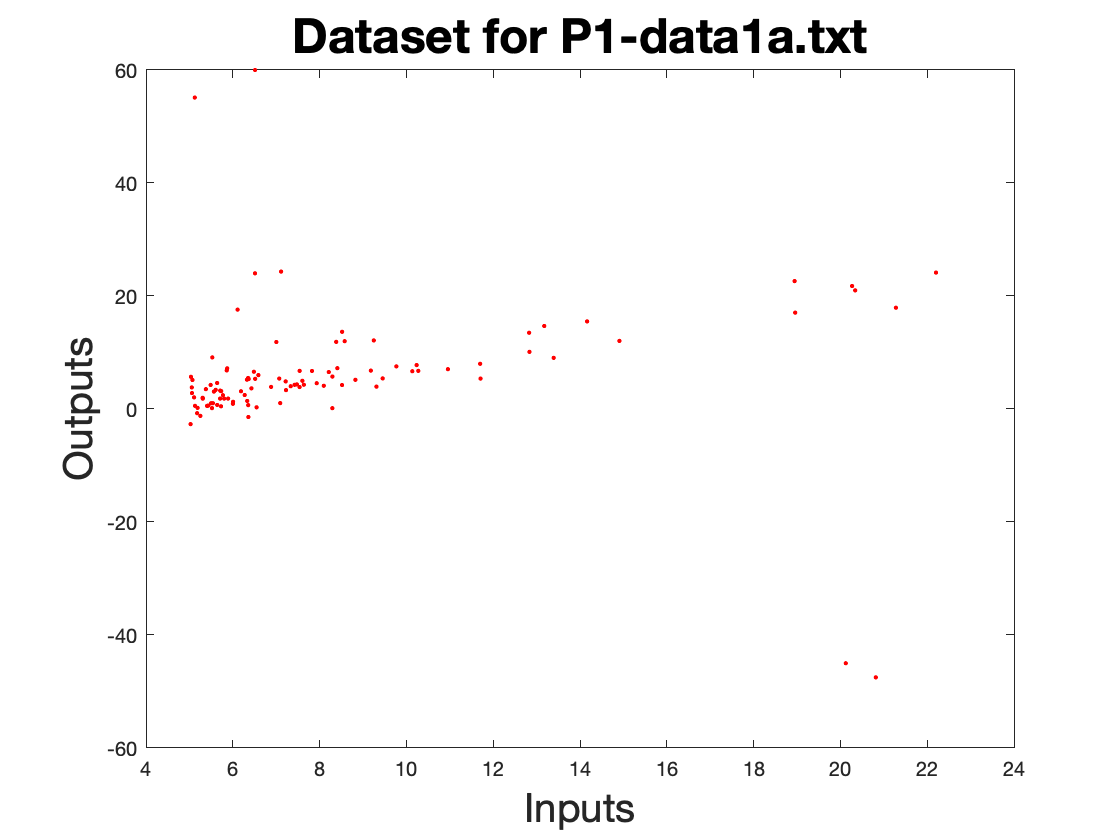


close all;
filename ='/Users/parisha/Desktop/AT-ML/ECE6604-MP1/Data sets/Linear regression/P1-data1a.txt';
delimiter = ',';

B = importdata(filename);
inputs_B= B(:,1);
outputs_B = B(:,2);
plot(inputs_B,outputs_B,'r.');
xlabel('Inputs',"FontSize",20);
ylabel('Outputs',"FontSize",20);
title('Dataset for P1-data1a.txt',"FontSize",24);

Here the number of outliers are more. So, as a loss function using mean absolute error or Huber loss function would be efficient. But, Mean absolute error function cannot be used with gradient descent method. Reason being, we cannot take gradient at 0. for simplicity using Huber Loss function is more efficient.

Let delta be 0.02. For range of (-0.02, 0.02) the loss function will behave like square loss function. and for out of the range, The loss function acts like mean absolute error.

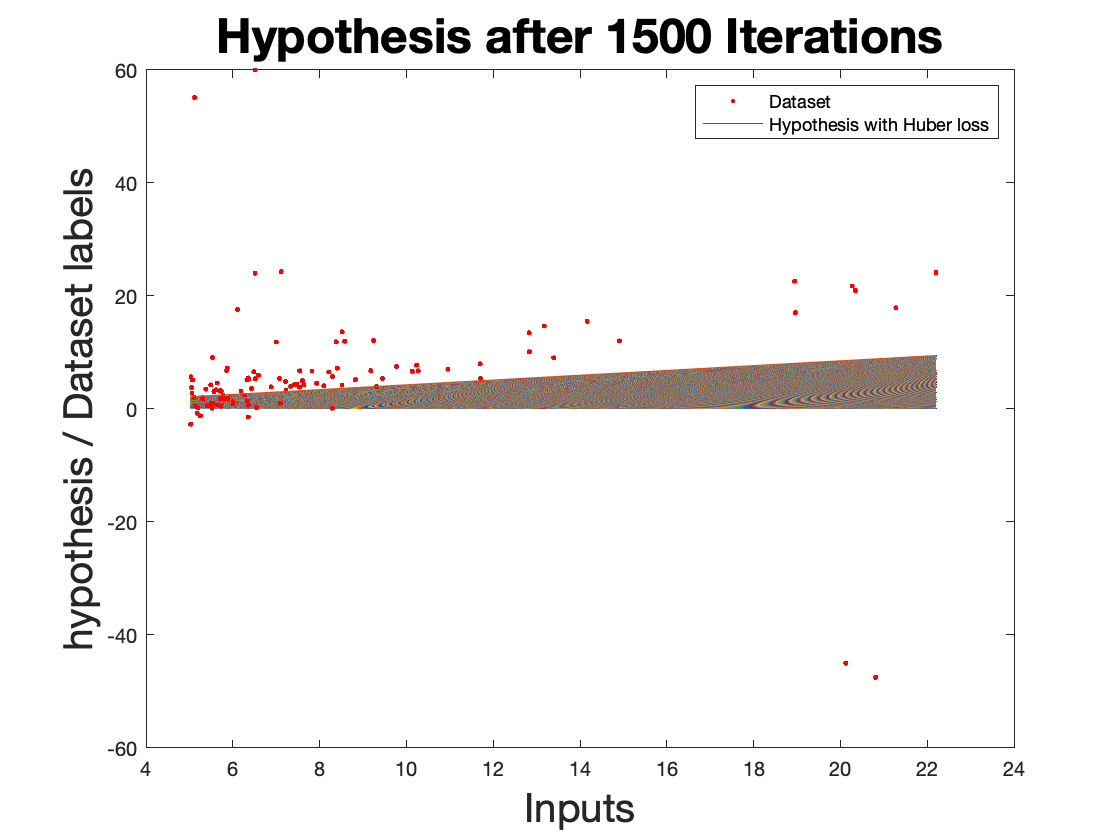

input_1x_B =[ones(1,length(inputs_B)); transpose(inputs_B)];
B_0=0;
B_1=0;
B_0_1=0;
B_1_1=0;
Beta = [B_0 B_1];
y_caps_B = zeros(length(inputs_B),1);
delta = 0.5;
Beta_update = zeros(length(inputs_B),2);
Beta_update_1 = zeros(length(inputs_B),2);

iterations = 1500;
learn_rate = 10^-6;

for itr = 1:iterations
    
    %part 1 to find y_cap - yi
    
    for i=1:length(y_caps_B)
        
        y_caps_B(i) = B_0 + B_1 * inputs_B(i);
        error= y_caps_B(i) - outputs_B(i);
        ab = abs(error);
       
         B_0_1 = B_0_1 - (learn_rate *error);
         B_1_1 = B_1_1 - (learn_rate *error*inputs_B(i));
         Beta_update_1(i,:) = [B_0_1 B_1_1];
        if ab< delta
             B_0 = B_0 - (learn_rate *error);
             B_1 = B_1 - (learn_rate *error*inputs_B(i));
           
        else 
             error = sign(y_caps_B(i) - outputs_B(i))*delta;
             B_0 = B_0 - (learn_rate *error);
             B_1 = B_1 - (learn_rate *error*inputs_B(i));
             
        end
        Beta_update(i,:) = [B_0 B_1];
        
    end
hyp_B = Beta_update(length(inputs_B),:) * input_1x_B;
hyp_B_1 = Beta_update_1(length(inputs_B),:) * input_1x_B;

plot(inputs_B,outputs_B,'r.');
hold on;
plot(inputs_B,hyp_B);

end
title('Hypothesis after 1500 Iterations',"FontSize",24);
ylabel('hypothesis / Dataset labels',"FontSize",20);
xlabel('Inputs',"FontSize",20);
legend({'Dataset','Hypothesis with Huber loss'});
hold off;

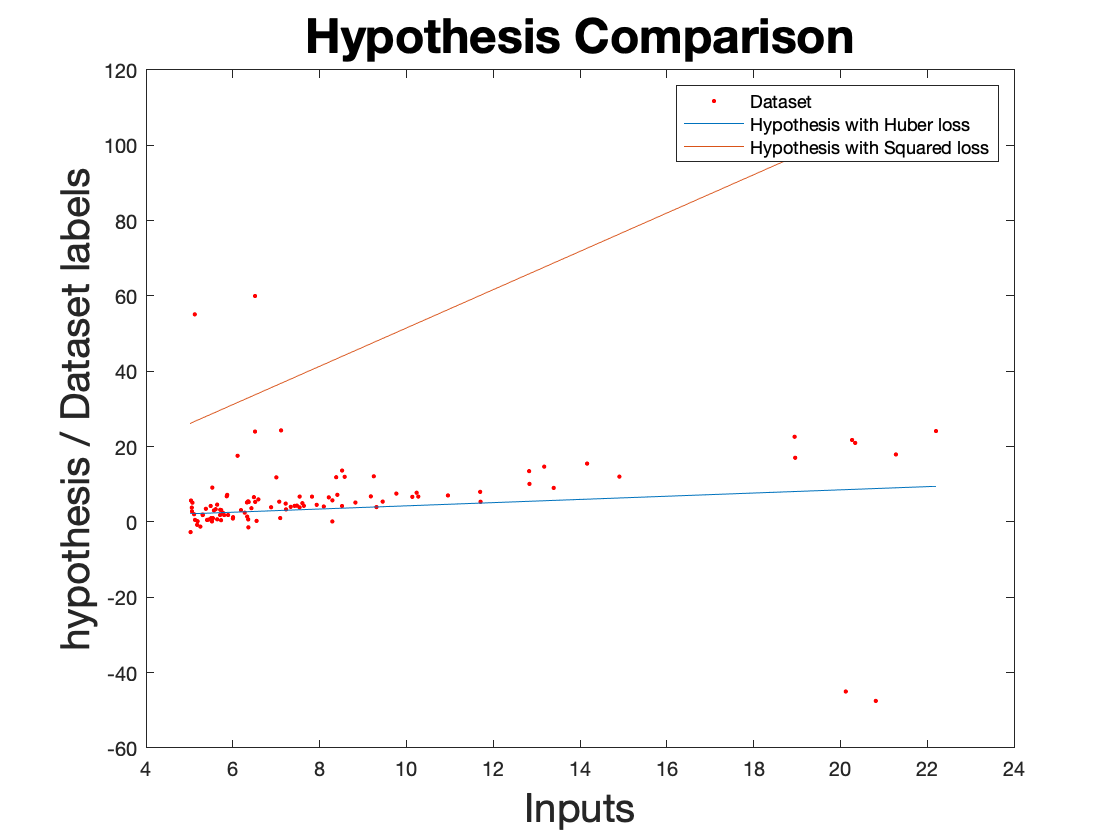


plot(inputs_B,outputs_B,'r.');
hold on
plot(inputs_B,hyp_B);
hold on;
plot(inputs_B,hyp_B_1);
title('Hypothesis Comparison',"FontSize",24);
ylabel('hypothesis / Dataset labels',"FontSize",20);
xlabel('Inputs',"FontSize",20);
legend({'Dataset','Hypothesis with Huber loss','Hypothesis with Squared loss'});
hold off;

Assumptions:

- Delta is take as close to 0 as possible hence, 0.02

- Number of iterations are taken as 1500.

- The learning rate is taken as 10^-6

Observations:

Using only least square method with outliers causes the gradient descent method to overshoot. The hypothesis is affected because of the outliers more in least square method than in Huber loss method. If the observation of outliers is necessary for the application then using least square method is efficient.Contrary to that, If we want to ignore the outliers and build a model robust to outliers, Using Huber method is efficient.